# Série 5

## Ex1

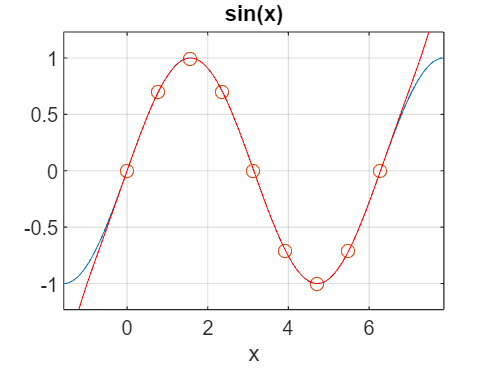

clear;clc;close;

f = @(x) sin(x);
% Point d'interpolation
x = linspace(0, 2*pi, 9);
y = f(x);

% Coefficients
a = polyfit(x, y, 8);

% Dessin des fonctions
ezplot(f, [-pi/2, 5*pi/2]);
grid on;
hold on;

% evaluation du polyonme en 1000 points
xx = linspace(-pi/2, 5*pi/2, 1e3);
p = polyval(a, xx);

plot(x, y, 'o', xx, p, 'r');

## Ex2

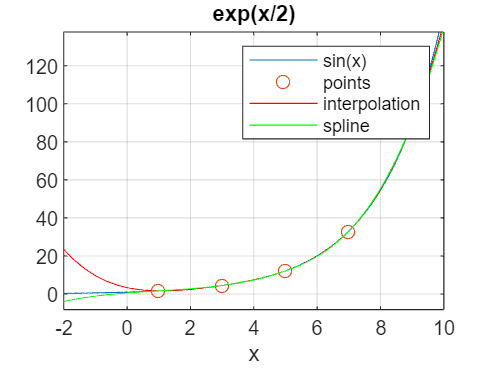

clear;clc;close;

f = @(x) exp(x/2);
% pts interpolation
x = linspace(1, 9, 5);
y = f(x);
% coeff
a = polyfit(x, y, 4);

% evaluation polynome
xx =  linspace(-2, 10, 1e3);
p = polyval(a, xx);

% dessin
ezplot(f, [-2, 10]); grid on; hold on;
plot(x, y, 'o', xx, p, 'r');

% Spline
p2 = spline(x, y, xx);
plot(xx, p2, 'g');
legend('sin(x)', 'points', 'interpolation', 'spline');
hold off;

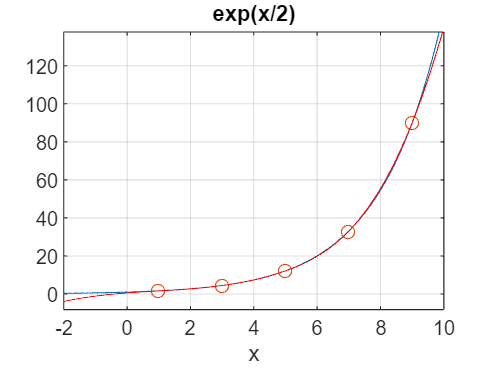

ezplot(f, [-2, 10]); grid on; hold on;
plot(x, y, 'o', xx, p2, 'r');

## Ex3

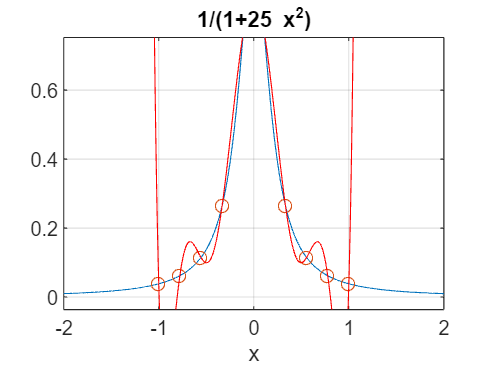

clear;clc;close;

f = @(x) 1./(1+25*x.^2);

x = linspace(-1, 1, 10);
y = f(x);

a = polyfit(x, y, 9);

xx = linspace(-2, 2, 1e3);
p = polyval(a, xx);

ezplot(f, [-2, 2]); hold on; grid on;
plot(x, y, 'o', xx, p, 'r');

## Ex4

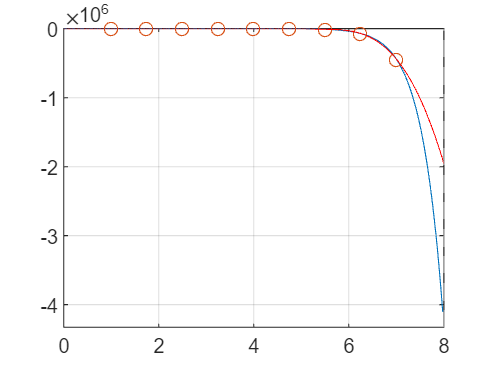

clear;clc;close;

f = @(x) exp(2*x).*cos(log(x));

% 9 points semble être un bon nombre
count = 9;

x = linspace(1, 7, count);
y = f(x);

xx = linspace(0, 8, 1e3);

p = spline(x, y, xx);

fplot(f, [0, 8]);
hold on; grid on;
plot(x, y, 'o', xx, p, 'r');

## Ex5

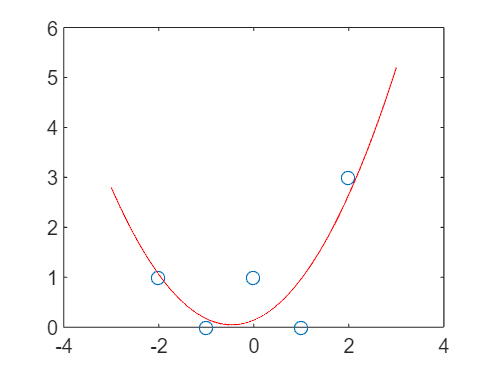

clear;clc;close;

x = -2:2;
y = [1 0 1 0 3];

xx = linspace(-3, 3, 1e3);

% Interpolation avec un polynome de degré 2:
a = polyfit(x, y, 2);
p = polyval(a, xx);
plot(x, y, 'o', xx, p, 'r');

% somme des carrés des résidus :
err_2 = sum((y - polyval(a, x)).^2)

err_2 = 1.8286

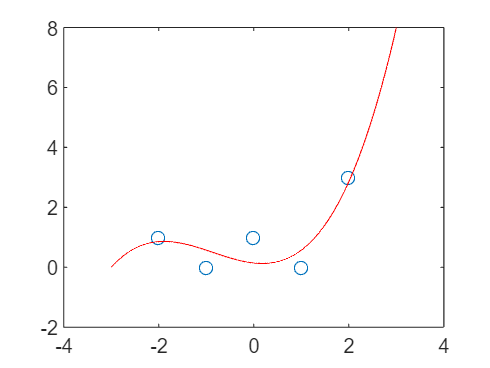



% Interpolation avec un polynome de degré 3:
a = polyfit(x, y, 3);
p = polyval(a, xx);
plot(x, y, 'o', xx, p, 'r');

% somme des carrés des résidus :
err_3 = sum((y - polyval(a, x)).^2)

err_3 = 1.4286

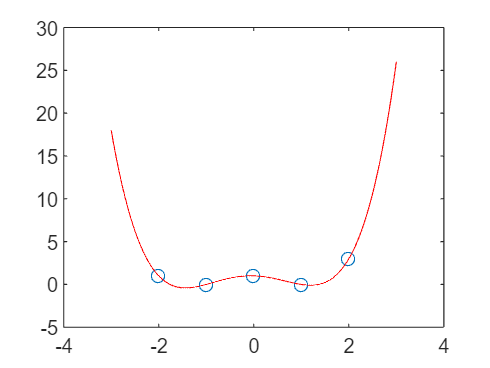



% Interpolation avec un polynome de degré 4:
a = polyfit(x, y, 4);
p = polyval(a, xx);
plot(x, y, 'o', xx, p, 'r');

% somme des carrés des résidus :
err_4 = sum((y - polyval(a, x)).^2)

err_4 = 1.4421e-30

## Ex6

clear;clc;close;

x = (0:3)'

x =      0
     1
     2
     3


y = [1 0 1 0]'

y =      1
     0
     1
     0



A = [ones(4,1), sin(x), cos(x)]

A =    1.0000e+00            0   1.0000e+00
   1.0000e+00   8.4147e-01   5.4030e-01
   1.0000e+00   9.0930e-01  -4.1615e-01
   1.0000e+00   1.4112e-01  -9.8999e-01



% Résolution modèle général : x = A\y
beta = A\y

beta =    5.0000e-01
  -1.4960e-02
   2.1095e-01


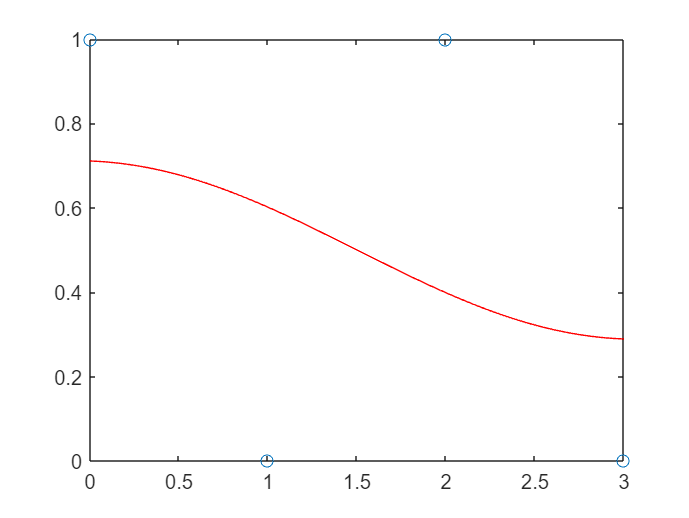


a0 = beta(1);
a1 = beta(2);
a2 = beta(3);

% Evaluation
p = @(x) a0 + a1*sin(x) + a2*cos(x);

xx = linspace(0, 3, 100);
yy = p(xx);

plot(x, y, 'o', xx, yy, 'r');


% Somme des carrés des résidus :
err = norm(p(x) - y)^2

err =    8.9044e-01


## Ex 6 corrigé

clear;clc;close;
x = [0, 1, 2, 3]'; y = [1, 0, 1, 0]';
X = [ones(size(x)), sin(x), cos(x)];
beta = X\y;
yy = beta(1) + beta(2)*sin(x) + beta(3)*cos(x);
err = norm(yy-y)^2

err =    8.9044e-01


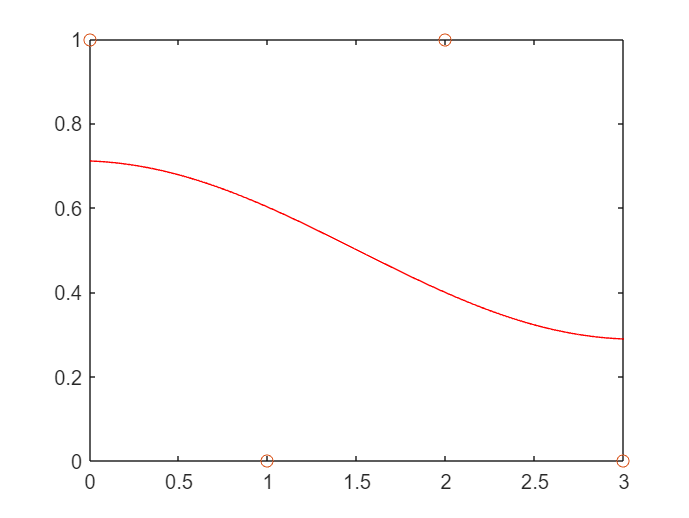

xx = linspace(0, 3, 1000);
yy2 = beta(1) + beta(2)*sin(xx) + beta(3)*cos(xx);
plot(xx, yy2, 'r', x, y, 'o')

## Ex 7

clear;clc;close;

% Forme log-lin
% y = ax^b

Annees = (1961:3:1982)

Annees =         1961        1964        1967        1970        1973        1976        1979        1982


Annees = [Annees 1984]'

Annees =         1961
        1964
        1967
        1970
        1973
        1976
        1979
        1982
        1984


Tonnes = [1900, 9500, 21200, 43300, 80300, 101600, 154900, 146300, 154500]'

Tonnes =         1900
        9500
       21200
       43300
       80300
      101600
      154900
      146300
      154500



% lny = lna + b*lnx
% v = lna + b*u
% v = c + b*u = A*beta

u = log(Annees)

u =     7.5812
    7.5827
    7.5843
    7.5858
    7.5873
    7.5888
    7.5903
    7.5919
    7.5929


v = log(Tonnes)

v =     7.5496
    9.1590
    9.9618
   10.6759
   11.2935
   11.5288
   11.9505
   11.8934
   11.9479



A = [u ones(size(u))]

A =     7.5812    1.0000
    7.5827    1.0000
    7.5843    1.0000
    7.5858    1.0000
    7.5873    1.0000
    7.5888    1.0000
    7.5903    1.0000
    7.5919    1.0000
    7.5929    1.0000



cond(A) % Précision ok

ans = 1.5245e+04


beta = A\v

beta = 1.0e+03 *

    0.3460
   -2.6143



% Régression du log(y)
p = beta(1)*u + beta(2);
% On prends la puissance pour avoir y
p = exp(p)

p = 1.0e+05 *

    0.0529
    0.0898
    0.1522
    0.2579
    0.4367
    0.7386
    1.2484
    2.1084
    2.9888


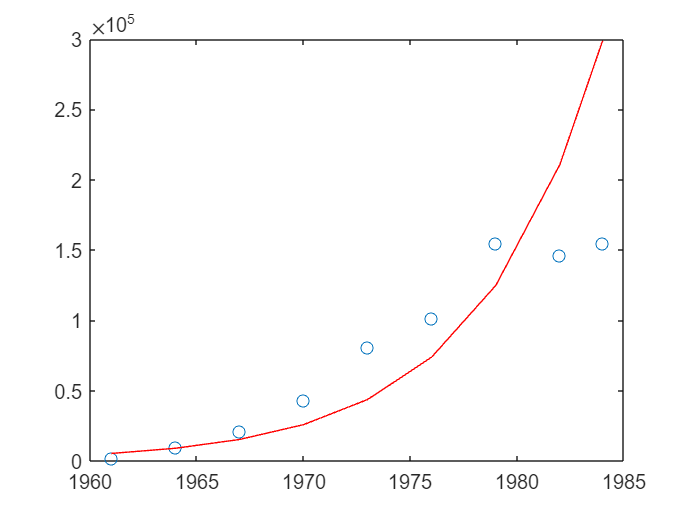

plot(Annees, Tonnes, 'o', Annees, p, 'r')

## Ex 7, 2

clear;clc;close;

annee = (1961:3:1982)

annee =         1961        1964        1967        1970        1973        1976        1979        1982


annee = [annee 1984]'

annee =         1961
        1964
        1967
        1970
        1973
        1976
        1979
        1982
        1984


masse = [1900, 9500, 21200, 43300, 80300, 101600, 154900, 146300, 154500]'

masse =         1900
        9500
       21200
       43300
       80300
      101600
      154900
      146300
      154500



x = annee - 1960

x =      1
     4
     7
    10
    13
    16
    19
    22
    24


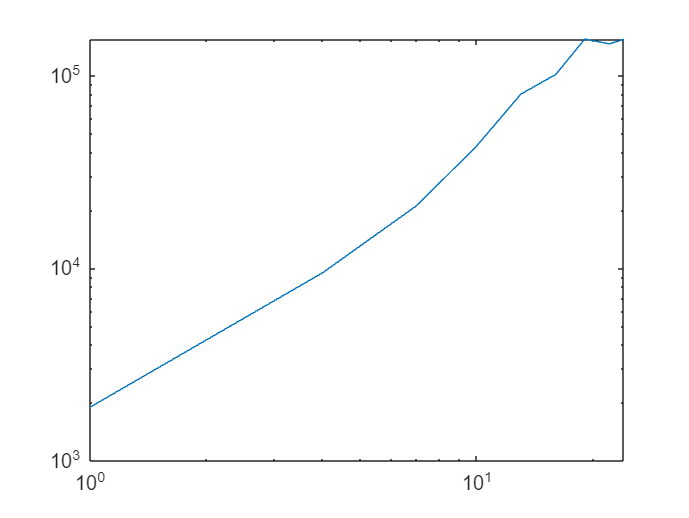

loglog(x, masse)


u = log(x)

u =          0
    1.3863
    1.9459
    2.3026
    2.5649
    2.7726
    2.9444
    3.0910
    3.1781


v = log(masse)

v =     7.5496
    9.1590
    9.9618
   10.6759
   11.2935
   11.5288
   11.9505
   11.8934
   11.9479



c = polyfit(u, v, 1)

c =     1.4761    7.3516


a = exp(c(2))

a = 1.5587e+03

b = c(1)

b = 1.4761


p = a*x.^b

p = 1.0e+05 *

    0.0156
    0.1206
    0.2756
    0.4665
    0.6871
    0.9336
    1.2031
    1.4938
    1.6985


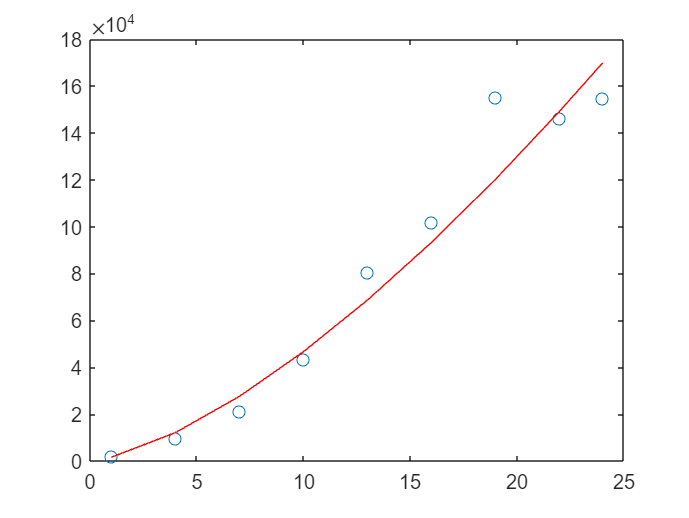


plot(x, masse, 'o', x, p, 'r');


% Calcul de l'erreur
err = norm(p - masse)^2

err = 1.7020e+09

## Ex8

data = [0.05 12.131; ...
        0.1 7.358; ...
        0.2 2.707; ...
        0.3 0.996; ...
        0.4 0.366; ...
        0.5 0.135];
t = data(:, 1)

t =     0.0500
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000


u = data(:, 2)

u =    12.1310
    7.3580
    2.7070
    0.9960
    0.3660
    0.1350



% u = V*exp(-t/T)
% lnu = v = at + c ; a = -1/T et c = lnV
v = log(u)

v =     2.4958
    1.9958
    0.9958
   -0.0040
   -1.0051
   -2.0025


A = [t t.^0]

A =     0.0500    1.0000
    0.1000    1.0000
    0.2000    1.0000
    0.3000    1.0000
    0.4000    1.0000
    0.5000    1.0000



beta = A\v

beta =    -9.9980
    2.9955


% p = polyval(beta, t);
% plot(t, v, 'o', t, p, 'r')

tt = linspace(0, 0.6, 100);
pp = exp(polyval(beta, tt))

pp =    19.9944   18.8189   17.7124   16.6710   15.6909   14.7683   13.9000   13.0828   12.3136   11.5896   10.9082   10.2668    9.6632    9.0951    8.5603    8.0570    7.5833    7.1374    6.7178    6.3228    5.9511    5.6012    5.2719    4.9619    4.6702    4.3956    4.1372    3.8939    3.6650    3.4495    3.2467    3.0558    2.8761    2.7070    2.5479    2.3981    2.2571    2.1244    1.9995    1.8819    1.7713    1.6671    1.5691    1.4768    1.3900    1.3083    1.2314    1.1590    1.0908    1.0267


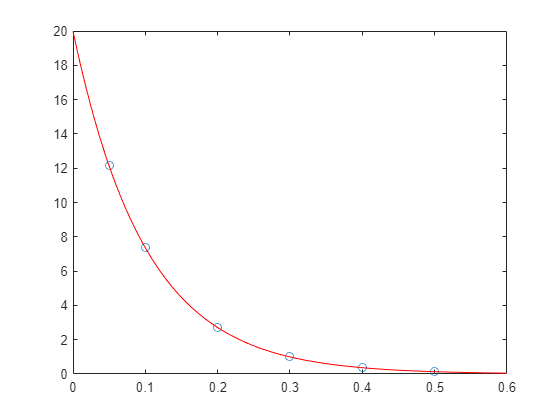

plot(t, u, 'o', tt, pp, 'r');


a = beta(1);
c = beta(2);
T = -1/a

T = 0.1000


% Resultats
v = exp(c)

v = 19.9944

R = 400

R = 400

C = T/R

C = 2.5005e-04